# TCLab PI Control

**Objective:** Implement a discrete PID controller without the derivative term (PI Control). Show the control performance with a setpoint change from $23 ^\circ\text{C}$ to $60 ^\circ\text{C}$.

A proportional integral (PI) controller is a variation of the PID controller without the derivative term. The controller is an equation that adjusts the controller output, $u(t)$, for input into the system as the manipulated variable. It is a calculation of the difference between the setpoint *SP* and process variable *PV*. The adjustable parameters are the controller gain, $K_c$, and controller reset time or integral time constant, $\tau_I$. A large gain or small integral time constant produces a controller that reacts aggressively to a difference between the measured PV and target SP.


$$Q(t) = Q_{bias} + K_c \, \left( T_{SP}-T_{PV} \right) + \frac{K_c}{\tau_I}\int_0^t  \left( T_{SP}-T_{PV} \right) dt$$



$$\quad = Q_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t  e(t) dt$$


The $Q_{bias}$ term is a constant that is typically set to the value of $Q(t)$ when the controller is first switched from manual to automatic mode. The deviation variable for the heater is the change in value $Q'(t)=Q(t)-Q_{bias}$. For the TCLab, $Q_{bias}=0$ because the TCLab starts with the heater off. The $Q_{bias}$ gives bumpless transfer if the error is zero when the controller is turned on. The error from the set point is the difference between the $T_{SP}$ and $T_{PV}$ and is defined as $e(t)=T_{SP}-T_{PV}$. The continuous integral is approximated in a discrete form as a summation of the error multiplied by the sample time.


$$\frac{K_c}{\tau_I}\int_0^t  e(t) dt \approx \frac{K_c}{\tau_I} \sum_{i=1}^{n_t} e_i(t)\Delta t$$


See *Lesson 12: PI Control* for additional information on PI Controllers. Use a basic tuning correlation with FOPDT parameters ($K_p$ and $\tau_p$) determined from the *TCLab Grapical Fitting* or *TCLab Regression* exercises (Classes 6 and 7).


$$K_c = \frac{1}{K_p} \quad \quad \tau_I = \tau_p$$


Fill in the values of $K_c$, $\tau_I$, and the PI equation in the code below. Add anti-reset windup to prevent the integral from accumulating when the heater is saturated at 0% or 100%.

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);
filename = "L12_TCLab_data.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_tclab = A(:,1);
    Q1 = A(:,2);
    SP1 = A(:,3);
    T1 = A(:,4);
    E1 = A(:,5);
    IE1 = A(:,6);
    disp('TCLab Data read from file')
catch

    Kc =  
    TauI =  
    
    % Initialize Arrays
    n = 600;
    tm_tclab = zeros(n,1); 
    T1 = ones(n, 1)*23.0;
    Q1 = zeros(n,1);
    E1 = zeros(n,1);
    IE1 = zeros(n,1);
    SP1 = ones(n, 1)*23.0;
    SP1(10:end) = 60.0;  % step setpoint from 23.0 to 60.0 degC
    
    % connect to TCLab
    lab = tclab;
    
    Q1_bias = 0.0;
    tic
    for i =2:n  

Each Second, the measurement is recorded. WRITE THE CODE FOR ERROR, INTEGRAL OF ERROR, AND THE HEATER SETTING BELOW

        tm_tclab(i) = toc;
        dt = tm_tclab(i) - tm_tclab(i-1);
        T1(i) = lab.T1;
        E1(i) =  ;   % Error Measurement at i
        IE1(i) =  ;  % Integral of Error Measurement at i
        Q1(i) =  ;   % Heater Setting

The heater setting has been clipped to the acceptable range: 0% - 100%. IMPLEMENT ANTI-RESET WINDUP IN ADDITION

        if Q1(i) > 100
             ;
            Q1(i) = 100;
        elseif Q1(i) < 0
             ;
            Q1(i) = 0;
        end
        
        % Pass Heater Setting to heater
        lab.Q1(Q1(i));
        
        % Print Status every 20 iterations
        if mod(i,20)==0
            fprintf('Time: %.4g (s) Temperature: %.4g (deg C) Heater: %.4g (%%)\n', toc, T1(i), Q1(i))
        end
        
        % wait for remainder of 1 sec
        pause(1-mod(toc,1));
    end
    lab.off
    clear lab
    
    % save
    A = [tm_tclab Q1 SP1 T1 E1 IE1]
    writematrix(A, absolute_path, 'Delimiter', ',')
end

figure(2)
subplot(3,1,1)
plot(tm_tclab, T1, 'r.')
hold on;
plot(tm_tclab, SP1, 'k-')
hold off;
legend({'TCLab' 'Setpoint'}, "Location", "best")
ylabel("Temperature")
subplot(3,1,2)
plot(tm_tclab, Q1, 'r-')
ylabel("Heater Setting")
subplot(3,1,3)
plot(tm_tclab, E1, tm_tclab, IE1)
legend({'Error' 'Integral of Error'}, "Location", "best")
xlabel("Time (s)")

## Solution

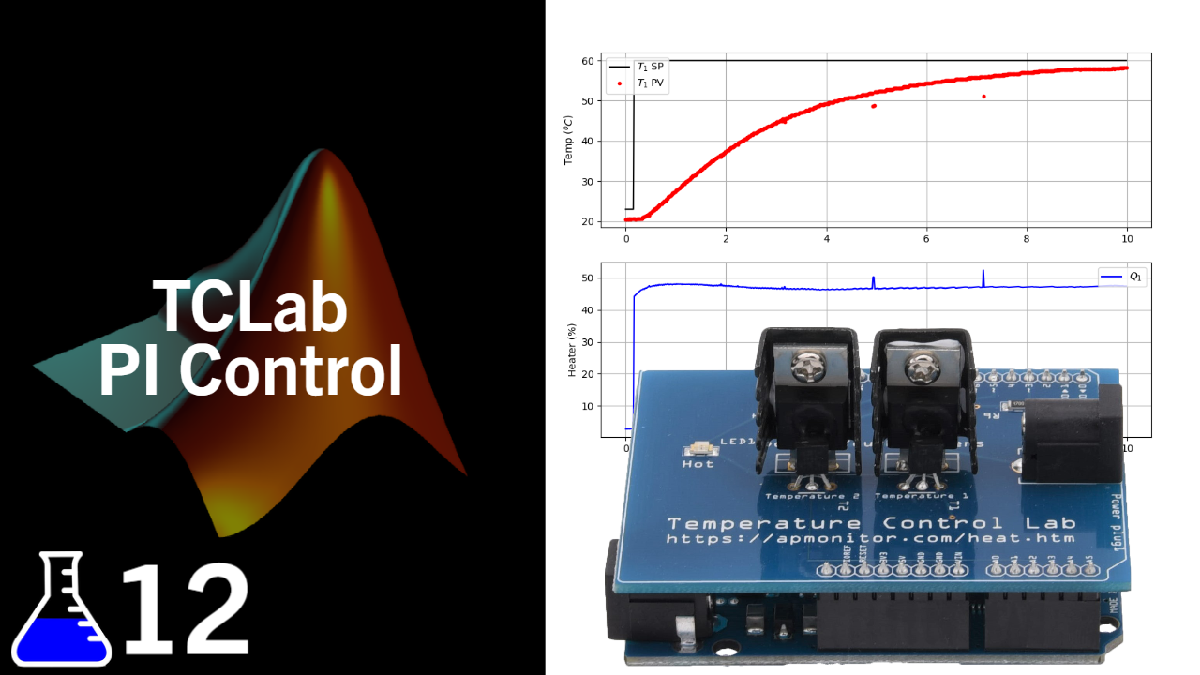

### [View Solution video](https://youtu.be/d8HXt4Sz1nk)